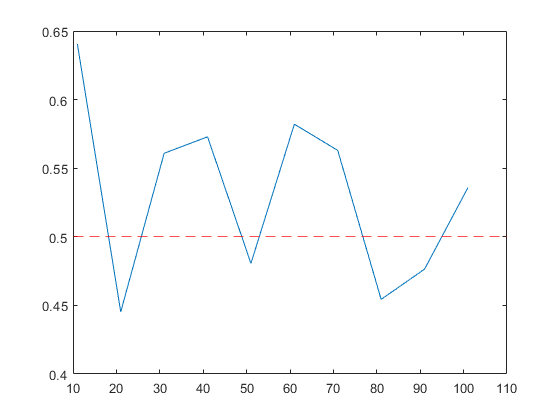

clear all;
close all;

n = 11;
true_mean = 0.5;
true_var = 1/12;
sample_mean = [];
sample_var = [];
lb = [];
ub = [];
t = [];
chi_avg_points1 = [20.483 34.17 43.773 59.342 71.420 83.298 95.023 106.629 118.136 129.561];
chi_avg_points2 = [3.247 9.591 16.791 24.443 32.357 40.482 48.758 57.153 65.647 74.222];

i = 1;
while n <= 101
    x = rand(n,1);
    sample_mean(end+1) = mean(x);
    sample_var(end+1) = var(x);
    if n<=21    %central theorem doesn't hold -> use bootstrap
        ci = bootci(10000,@var,x);
        ub(end+1) = ci(2);
        lb(end+1) = ci(1);
    end
    if n>=31
        bound = (n-1)*var(x);
        lb(end+1) = bound/chi_avg_points1(i);
        ub(end+1) = bound/chi_avg_points2(i);
        i = i + 1;
    end
    t(end+1) = n;
    n = n+10;
end

plot(t,sample_mean);
hold on
yline(true_mean,'--r');
hold off

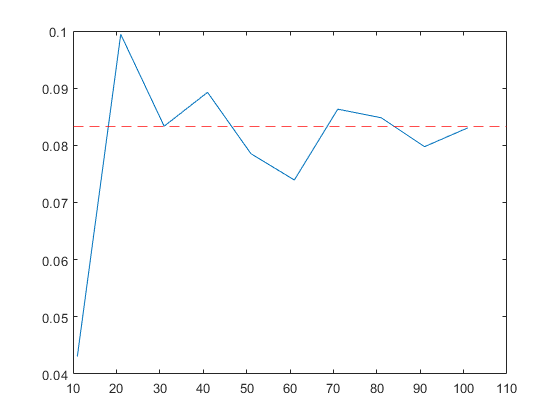

plot(t,sample_var);
hold on
yline(true_var,'--r');
hold off

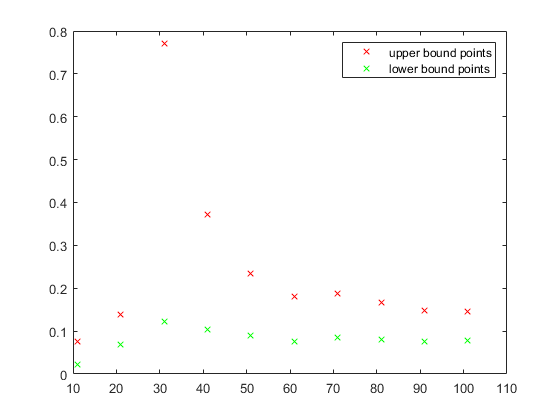

plot(t,ub,'xr');
hold on
plot(t,lb,'xg');
hold off
legend('upper bound points','lower bound points');

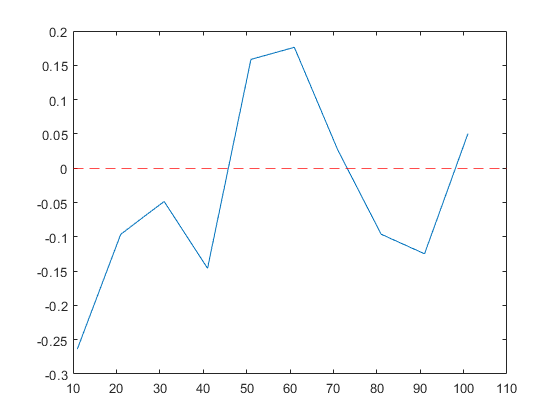


n = 11;
ub = [];
lb = [];
i=0;
t = [];
true_mean = 0;
true_var = 1;
sample_mean = [];
sample_var = [];

while(n<=101)
    i = i + 1;
    x = randn(n,1);
    sample_mean(end+1) = mean(x);
    sample_var(end+1) = var(x);
    bound = (n-1)*var(x);
    lb(end+1) = bound/chi_avg_points1(i);
    ub(end+1) = bound/chi_avg_points2(i);
    t(end+1) = n;
    n = n+10;
end

plot(t,sample_mean);
hold on
yline(true_mean,'--r');
hold off

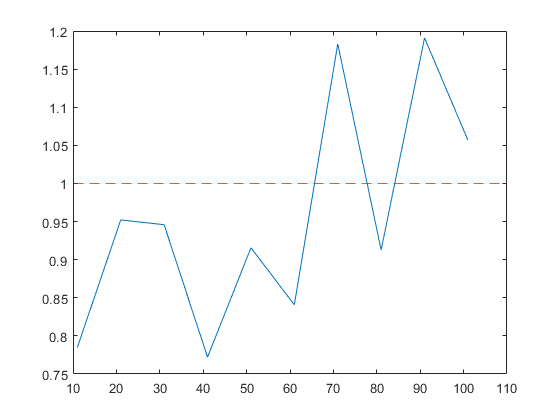

plot(t,sample_var);
hold on
yline(true_var,'--r');
hold off

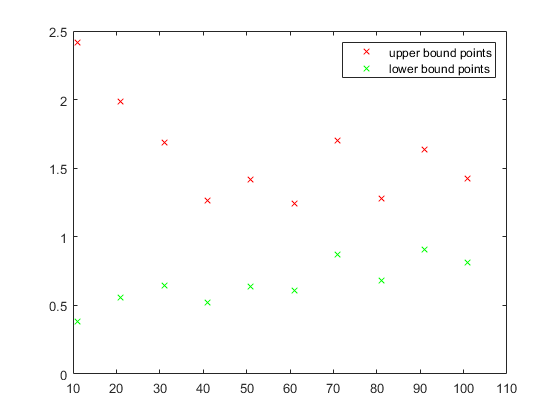

plot(t,ub,'xr');
hold on
plot(t,lb,'xg');
hold off
legend('upper bound points','lower bound points');


n = 999;
x = rand(n,1);
%x = randn(n,1);
x_sorted = sort(x,'ascend');
alpha = 0.05;
lb_idx = floor((n+1)*alpha/2);
ub_idx = ceil((n+1)*(1-alpha/2));
lb = x_sorted(lb_idx)

lb = 0.0206

ub = x_sorted(ub_idx)

ub = 0.9748


%find 95% PI by: taking an additional sampling with replacement from the
%dataset; taking as current PI the extremes of the sorted dataset; test if
%the sample doesn't lie in the just built PI; repeat this last step for k
%times and count the failures; repeat everything for the length of the
%dataset by shrinking the PI by one from each extreme every time
c = 0;
for k=1:length(x_sorted)
    lbb = x_sorted(k);
    ubb = x_sorted(end-k);
    for j=1:10000
        sample = x(randi(length(x)));
        if sample < lbb || sample > ubb
            c = c+1;
        end
    end
    c = c*100/10000
    if c >= 4.9
        break;
    end
end

c = 0.1700

c = 0.3417

c = 0.5934

c = 0.7059

c = 1.0871

c = 1.1309

c = 1.3613

c = 1.6536

c = 1.6665

c = 1.9867

c = 2.1199

c = 2.5912

c = 2.4059

c = 2.4841

c = 2.8748

c = 3.3187

c = 3.5632

c = 3.7056

c = 4.2171

c = 4.1122

c = 4.3011

c = 4.3030

c = 4.4630

c = 4.9646


lbb

lbb = 0.0203

ubb

ubb = 0.9748